clc;clear

## Aufgabe1

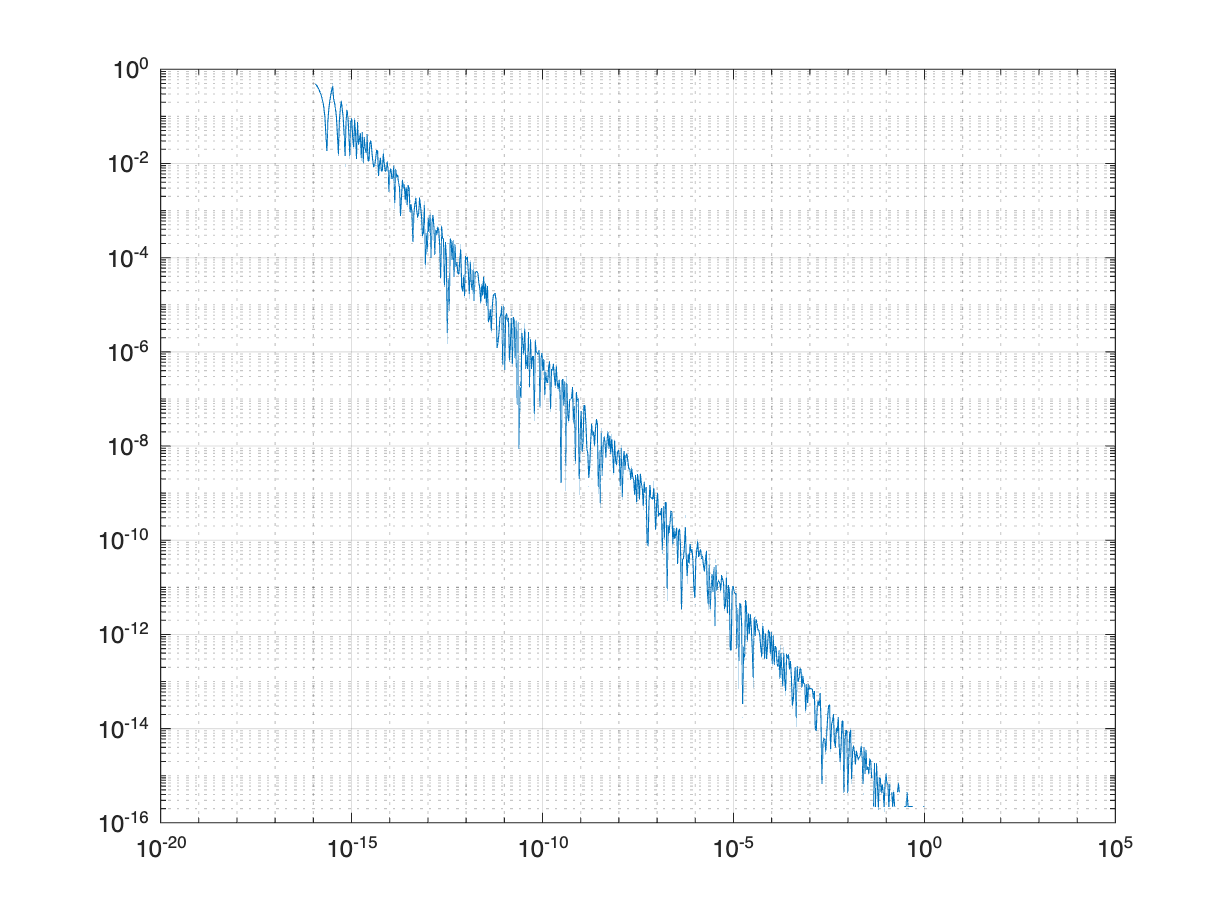

clc;clear;
delta = logspace(-20,5,1000);

x = zeros(1,length(delta));
y = zeros(1,length(delta));
x_exact = 1.0; % 
for i = 1:length(delta)
%     delta = 10 ^ (i -21);
    P1 = [0. 1.];
    P2 = [delta(i)  1. + delta(i)];
    x(:,i) = delta(i);
    x_num = lineintersection(P1,P2);
    y(:,i) = abs(x_exact - x_num);
end

loglog(x,y);
grid on

## Aufgabe 2

clc;clear;
format long

x_node = [0.0 1.0 2.0 3.0 4.0];
f_node = [0.0 0.031250 0.131687 0.237304 0.327680];

x = 0:0.01:4;
y = (x./(x+1)).^5;
% 0.6 是要推断的点

### 2.1 Grad 1

f1 = LagrangePolynom(0.6,1,x_node,f_node)

f1 =    0.018750000000000


df1 = LagrangeDerivPolynom(0.6,1,x_node,f_node)

df1 =    0.031250000000000


## 2.2 Grad 4

f4 = LagrangePolynom(0.6,4,x_node,f_node)

f4 =    0.005398678400000


df4 = LagrangeDerivPolynom(0.6,4,x_node,f_node)

df4 =    0.046592649333333


### 2.3 Grad 80

% 不使用原来的 x, fx, 而是使用[0.0,4.0]区间内的 x 和对应的 y
x80 = 0:0.05:4;
y80 = (x80./(x80+1)).^5;
f80 = LagrangePolynom(0.6,80,x80,y80)

f80 =    0.007415771484375


df80 = LagrangeDerivPolynom(0.6,80,x80,y80)

df80 =    0.038623370313570


### Plot

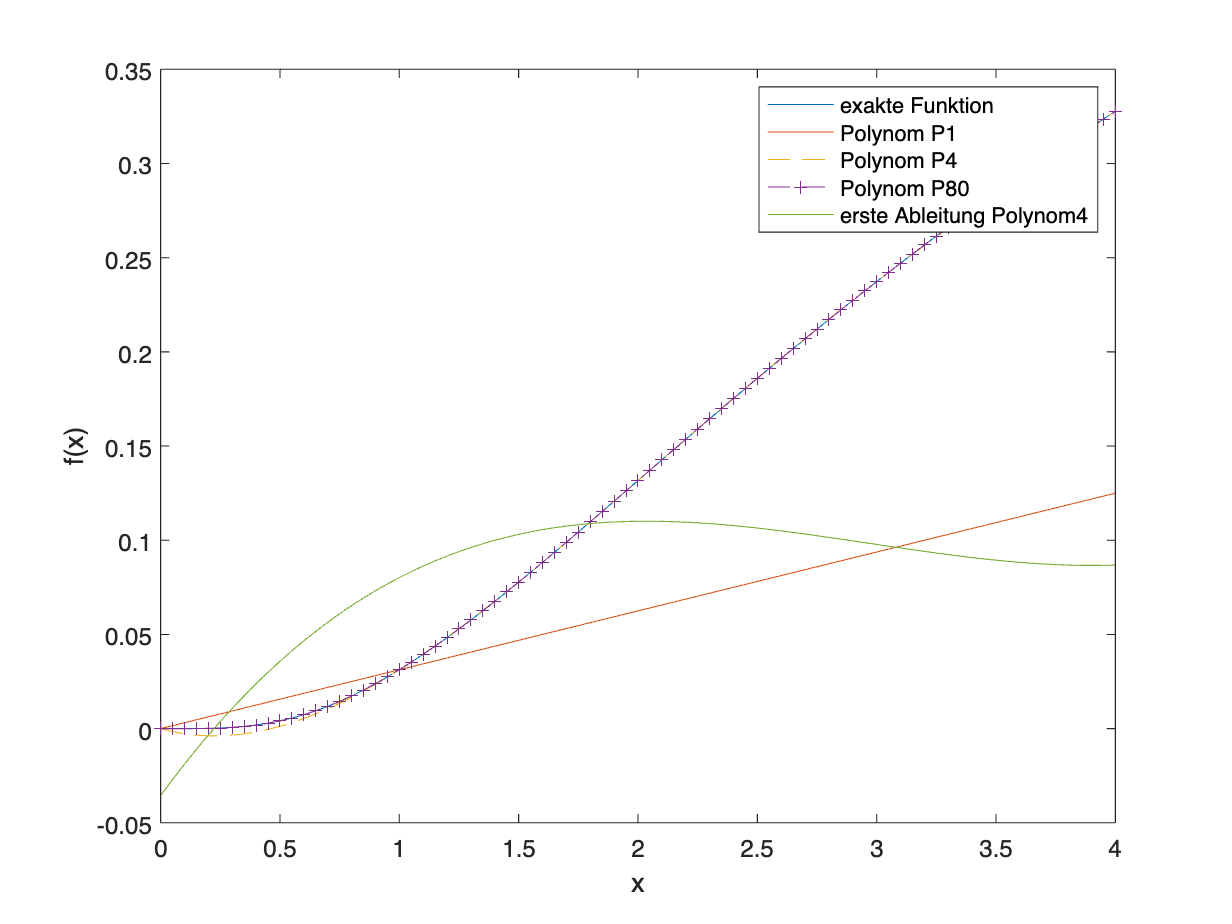

plot(x,y,...
    x,LagrangePolynom(x,1,x_node,f_node),...
    x,LagrangePolynom(x,4,x_node,f_node),'--',...
    x80,LagrangePolynom(x80,80,x80,y80),'--+',...
    x,LagrangeDerivPolynom(x,4,x_node,f_node))
xlabel('x');
ylabel('f(x)');
legend('exakte Funktion','Polynom P1','Polynom P4',...
    'Polynom P80','erste Ableitung Polynom4')

function  x_numeric = lineintersection(P1,P2)
% "计算两个点的交点的数值解";
% y= kx+b y=2, b=1
% k=(y2-y1)/(x2-x1)
k = (P2(2) - P1(2))/(P2(1) - P1(1));
x_numeric = 1/k ;
end

function wert_basis = LagrangeBasis(x,n,i,x_node)
 wert_basis = 1;
for k = 1: n+1
    if k ~= i
        wert_basis = wert_basis .* (x - x_node ...
            (k))./(x_node(i) - x_node(k));
%     else
%         wert_basis = wert_basis*1;
    end
end
end

function wert_poly = LagrangePolynom(x,n,x_node,f_node)
wert_poly = 0;
% 原版是 k = 1: n+1 , i 对应课件
for i = 1: n+1
    wert_poly = wert_poly + LagrangeBasis(x,n,i,x_node).*f_node(i);
end
end

function wert_dBasis = LagrangeDerivBasis(x,n,i,x_node)
wert_dBasis=0;
for m=1:n+1
    value_inner=1;
    if m~=i
        for k=1:n+1
            
            if k~=i && k~=m
                value_inner=value_inner.*(x-x_node(k))/(x_node(i)-x_node(k));
            
            % else
            %     value_inner = 1.*value_inner;
            end
        end
       
        wert_dBasis = wert_dBasis + value_inner ./ (x_node(i) - x_node(m));
    % else
    %     wert_dBasis=wert_dBasis;
    end

end
end

function wert_dpoly = LagrangeDerivPolynom(x,n,x_node,f_node)
wert_dpoly = 0;
for i = 1:n+1
    wert_dpoly = wert_dpoly + LagrangeDerivBasis(x,n,i,x_node).*f_node(i);
end
end